## **Stewart Platform Simulation**

The purpose of this script is to show the calculations needed for a stewart platform and help select parameters for the platform.

### **Constant Values **

P = 150; % Platform size constant (mm)
B = 100; % Base size constant (mm)

a = 1; % Controlled arm length (mm)
b = 1; % Uncotrolled arm (mm)

h_0 = 100 ; % Default platform height

### **Inputed command**

pitch =13

pitch = 13

roll = 6.5

roll = 6.5000

z =    3.1

z = 3.1000

### **Platform and Base Vectors **

p1 = (P * [cosd(0) sind(0) 0])';
p2 = (P * [cosd(120) sind(120) 0])';
p3 = (P * [cosd(240) sind(240) 0])';

B1 = (B * [cosd(0) sind(0) 0])';
B2 = (B * [cosd(120) sind(120) 0])';
B3 = (B * [cosd(240) sind(240) 0])';

### **Rotation Matrix Calculation**

R = calculateRotationMatrix(pitch, roll)

R =     0.9744    0.0255    0.2235
         0    0.9936   -0.1132
   -0.2250    0.1103    0.9681


T = ([0 0 h_0] + [0 0 z])';

P1 = (T + R * p1)'

P1 =   146.1555         0   69.3573


P2 = (T + R * p2)'

P2 =   -69.7697  129.0688  134.3000


P3 = (T + R * p3)'

P3 =   -76.3858 -129.0688  105.6427



X = [P1(1), P2(1), P3(1), B1(1), B2(1), B3(1)];
Y = [P1(2), P2(2), P3(2), B1(2), B2(2), B3(2)];
Z = [P1(3), P2(3), P3(3), B1(3), B2(3), B3(3)];

### **Calculating l_i vectors**

l1 = (T + R*p1 - B1)'

l1 =    46.1555         0   69.3573


l2 = (T + R*p2 - B2)'

l2 =   -19.7697   42.4662  134.3000


l3 = (T + R*p3 - B3)'

l3 =   -26.3858  -42.4662  105.6427



phi1 = atand(l1(2)/l1(1))

phi1 = 0

phi2 = atand(l2(2)/l2(1))

phi2 = -65.0361

phi3 = atand(l3(2)/l3(1))

phi3 = 58.1458

### **3D Plot**

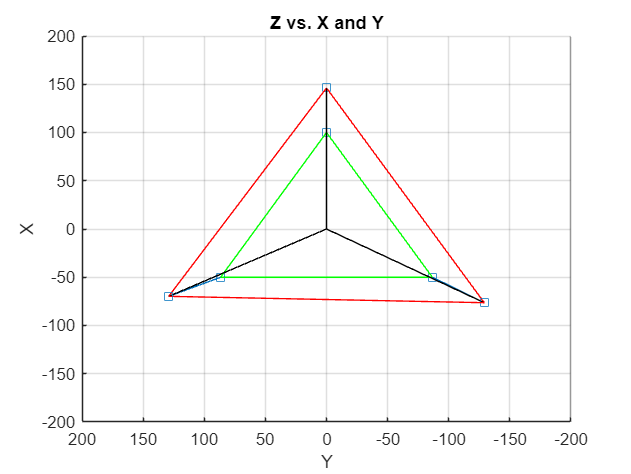

% Create scatter3 of X, Y, and Z
s = scatter3(X,Y,Z,"Marker","square","DisplayName","Z");

% Add xlabel, ylabel, zlabel, title, and legend
axis([-B B -B B 0 10])
xlabel("X")
ylabel("Y")
zlabel("Z")
title("Z vs. X and Y")
line([X(1),X(2), X(3), X(1)], [Y(1), Y(2), Y(3), Y(1)], [Z(1), Z(2), Z(3), Z(1)], 'Color', 'r')
line([X(4),X(5), X(6), X(4)], [Y(4), Y(5), Y(6), Y(4)], [Z(4), Z(5), Z(6), Z(4)], 'Color', 'g')
line([X(1), X(4)], [Y(1), Y(4)], [Z(1), Z(4)])
line([X(2), X(5)], [Y(2), Y(5)], [Z(2), Z(5)])
line([X(3), X(6)], [Y(3), Y(6)], [Z(3), Z(6)])
line([0, T(1)], [0, T(2)], [0, T(3)], "Color", "black")
line([X(1),T(1), X(2), T(1),  X(3), T(1), X(1)], [Y(1),T(2), Y(2), T(2), Y(3), T(2), Y(1)], [Z(1), T(3), Z(2), T(3), Z(3), T(3), Z(1)], 'Color', 'black')

xlim([-2*B 2*B])
ylim([-2*B 2*B])
zlim([0 200])

view([-104 10])

view([-90, 90])